DATA= readtable("Training data.xlsx","TextType","string")

DATA = 9417×2 table
             Measure_Name                                                              Description                                                 
    ______________________________    _____________________________________________________________________________________________________________

    "Bulb - Exterior"                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    "Bulb - Exterior"                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    "Bulb - Exterior"                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    "Lighting Controls - Exterior"    ""(1) 2-pole circuit dimmer lighting""                                                                       
    "VFD - Cooling"    


DATA.Measure_Name = categorical(DATA.Measure_Name)

DATA = 9417×2 table
            Measure_Name                                                             Description                                                 
    ____________________________    _____________________________________________________________________________________________________________

    Bulb - Exterior                 ""(1) 12w ledt8 lamp + 1l ballast lighting""                                                                 
    Bulb - Exterior                 ""(1) 16.5w led instantfit tubes & 1-lamp none advance ballast lighting""                                    
    Bulb - Exterior                 ""(1) 16.5w ledt8 lamp + 1h ballast lighting""                                                               
    Lighting Controls - Exterior    ""(1) 2-pole circuit dimmer lighting""                                                                       
    VFD - Cooling                  

summary(DATA.Measure_Name)

     Air Compressor                        63 
     Air Nozzle                             2 
     Air Sealing                          136 
     Air Source                            21 
     Appliance Removal                    113 
     Boiler                               128 
     Boiler Reset Control                  21 
     Building Operator Certification        2 
     Bulb - Exterior                      537 
     Bulb - Interior                        4 
     CHP                                   26 
     Central AC                            20 
     Chiller                               59 
     Circulator Pump                       16 
     Clothes Dryer                          8 
     Clothes Washer    

Labeldata=DATA(ismember(DATA.Measure_Name,"Fee"),:)

Labeldata = 238×2 table
    Measure_Name                               Description                            
    ____________    __________________________________________________________________

        Fee         ""1-day lift cost lighting""                                      
        Fee         ""100% electric admin fee lighting""                              
        Fee         ""100% electric admin fee other""                                 
        Fee         ""100% gas admin fee heating""                                    
        Fee         ""2017 admin fee lighting""                                       
        Fee         ""30 feet lift cost per day - 30 lighting""                       
        Fee         ""30 feet lift cost per day lighting""                            
        Fee         ""30 feet lift cost per week - 30 lighting""                      
        Fee         ""30 feet lift co

Labeldata_D=string(Labeldata.Description)

Labeldata_D = 238×1 string array
    ""1-day lift cost lighting""
    ""100% electric admin fee lighting""
    ""100% electric admin fee other""
    ""100% gas admin fee heating""
    ""2017 admin fee lighting""
    ""30 feet lift cost per day - 30 lighting""
    ""30 feet lift cost per day lighting""
    ""30 feet lift cost per week - 30 lighting""
    ""30 feet lift cost per week lighting""
    ""3719861 | lighting | lift | 30 feet lift cost per day - 30 n/a""
    ""3973345 | lighting | lift | 30 feet lift cost per day - 30 n/a""
    ""39w flood light w/extra wirring fee lighting""
    ""40 feet lift cost per day - 40 lighting""
    ""40 feet lift cost per day lighting""
    ""40 feet lift cost per week - 40 lighting""
    ""40 feet lift cost per week lighting""
    ""40 foot lift - cost per week lighting""
    ""50 feet lift cost per day - 50 lighting""
    ""50 feet lift cost per day lighting""
    ""50 feet lift cost per week - 50 lighting""
    ""50 feet lift cost per week lighti

    % Convert to numeric
    Labeledior2Num = pdist(Labeldata_D)

Labeledior2Num =   304.8114  279.3278  240.3206  186.8181  313.2475  311.9904  317.2034  315.9620  424.5327  424.6728  367.0572  313.3177  311.9984  317.2728  315.9699  349.5712  313.3943  312.0096  317.3484  315.9810  312.0240  315.9953  312.1122  317.8081  316.0823  537.6876  591.8480  331.2884  104.2593  356.8837  456.5107  423.2777  447.0962  658.3973  541.7241  274.4485  199.5745  133.0413  295.5503  269.1914  202.5414  201.7845  270.8450  251.1951  239.7853  253.6356  375.0267  317.6303  230.1152  207.0628


    labeledLink = linkage(Labeledior2Num,"ward")

labeledLink = 	1.0e+03 *

    0.0190    0.0220    0.0010
    0.0070    0.0140    0.0010
    0.0210    0.0230    0.0010
    0.0090    0.0160    0.0010
    0.0940    0.0950    0.0010
    0.0080    0.0150    0.0014
    0.0060    0.0130    0.0014
    0.0200    0.2440    0.0024
    0.0180    0.2450    0.0024
    0.2390    0.2400    0.0028


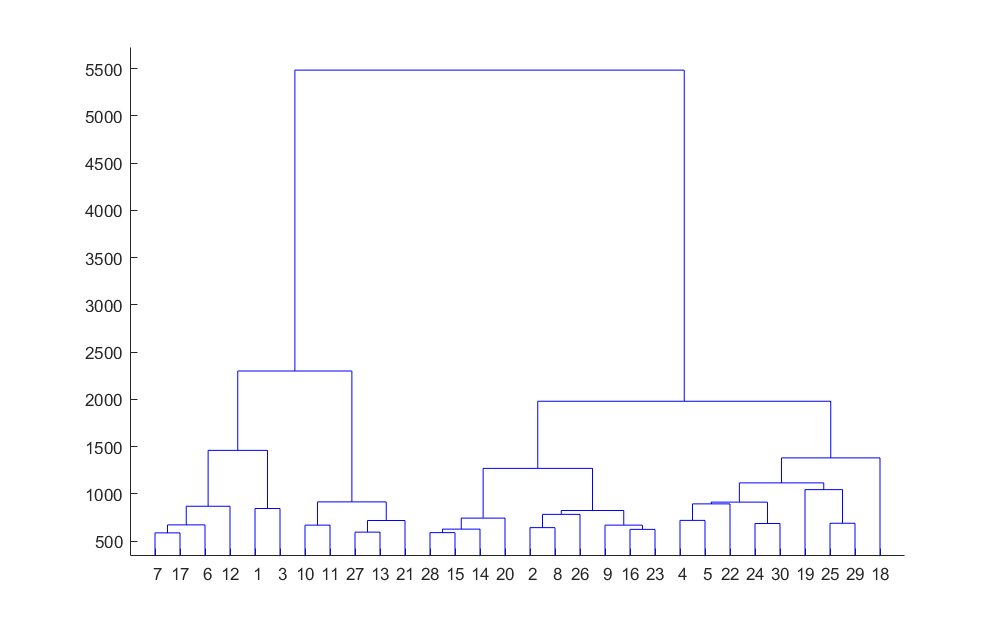

   
    % View tree
    dendrogram(labeledLink)


    % Accuracy Measure
    Labeled_ACC = cophenet(labeledLink,Labeledior2Num)

Labeled_ACC = 0.8177

    % Use inconsistency Coeff to help decide optimal # of cluster
    Labeled_I = inconsistent(labeledLink)

Labeled_I = 	1.0e+03 *

    0.0010         0    0.0010         0
    0.0010         0    0.0010         0
    0.0010         0    0.0010         0
    0.0010         0    0.0010         0
    0.0010         0    0.0010         0
    0.0014         0    0.0010         0
    0.0014         0    0.0010         0
    0.0019    0.0007    0.0020    0.0007
    0.0019    0.0007    0.0020    0.0007
    0.0016    0.0011    0.0030    0.0012


   
   Numberofcluster=2

Numberofcluster = 2

   
     % Agglomerative Heirarichical Cluster
     Labeled_Cluster = cluster(labeledLink,"maxclust",Numberofcluster)

Labeled_Cluster =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


   
     % Assign Cluster to Measure name
     Labeled_Idx = table(Labeldata_D,Labeled_Cluster)

Labeled_Idx = 238×2 table
                               Labeldata_D                                Labeled_Cluster
    __________________________________________________________________    _______________

    ""1-day lift cost lighting""                                                 2       
    ""100% electric admin fee lighting""                                         2       
    ""100% electric admin fee other""                                            2       
    ""100% gas admin fee heating""                                               2       
    ""2017 admin fee lighting""                                                  2       
    ""30 feet lift cost per day - 30 lighting""                                  2       
    ""30 feet lift cost per day lighting""                                       2       
    ""30 feet lift cost per week - 30 lighting""                                 2       
    "


Cluster_1 = Labeled_Idx(Labeled_Cluster == 1,"Labeldata_D")

Cluster_1 = 102×1 table
                                                                 Labeldata_D                                                              
    ______________________________________________________________________________________________________________________________________

    ""adding dollars in effort to repair, if not repaired will add 2 speed controls refrigeration""                                       
    ""additional labor costs for installing additional materials/running power for fixtures over bar. lighting""                          
    ""air sealing | eei_incentive_air | air sealing | rcs_air sealing incentive | fee | eei_incentive_air | incentive fee""               
    ""air sealing | eei_incentive_air | air sealing | rcs_air sealing incentive | fee | rcs_airsealingincentive | incentive fee""         
    ""air sealing | eei_incentive_air_r | air sealing | rcs air sealing incentive renter | fee | rcs_airsea

Cluster_2 = Labeled_Idx(Labeled_Cluster == 2,"Labeldata_D")

Cluster_2 = 136×1 table
                               Labeldata_D                            
    __________________________________________________________________

    ""1-day lift cost lighting""                                      
    ""100% electric admin fee lighting""                              
    ""100% electric admin fee other""                                 
    ""100% gas admin fee heating""                                    
    ""2017 admin fee lighting""                                       
    ""30 feet lift cost per day - 30 lighting""                       
    ""30 feet lift cost per day lighting""                            
    ""30 feet lift cost per week - 30 lighting""                      
    ""30 feet lift cost per week lighting""                           
    ""3719861 | lighting | lift | 30 feet lift cost per day - 30 n/a""
    ""3973345 | lighting | lift | 30 feet lift cost per day - 30 n/a""
    ""39w flood li


Cluster_1_CL=preprocessText(Cluster_1.Labeldata_D)

Cluster_1_CL =   102×1 tokenizedDocument:

     9 tokens: adding dollars effort repair repaired add speed controls refrigeration
    11 tokens: additional labor costs installing additional materials running power fixtures bar lighting
    12 tokens: air sealing eeiincentiveair air sealing rcsair sealing incentive fee eeiincentiveair incentive fee
    12 tokens: air sealing eeiincentiveair air sealing rcsair sealing incentive fee rcsairsealingincentive incentive fee
    14 tokens: air sealing eeiincentiveairr air sealing rcs air sealing incentive renter fee rcsairsealingincentive incentive fee
    12 tokens: air sealing electric eeiincentiveair rcsair sealing incentive fee eeiincentiveair air sealing fee
    12 tokens: air sealing electric eeiincentiveair rcsair sealing incentive fee rcsairsealingincentive air sealing fee
    14 tokens: air sealing electric eeiincentiveairr rcs air sealing incentive renter fee rcs

Cluster_2_CL=preprocessText(Cluster_2.Labeldata_D)

Cluster_2_CL =   136×1 tokenizedDocument:

     4 tokens: 1day lift cost lighting
     5 tokens: 100 electric admin fee lighting
     4 tokens: 100 electric admin fee
     5 tokens: 100 gas admin fee heating
     4 tokens: 2017 admin fee lighting
     6 tokens: feet lift cost per day lighting
     6 tokens: feet lift cost per day lighting
     6 tokens: feet lift cost per week lighting
     6 tokens: feet lift cost per week lighting
     8 tokens: 3719861 lighting lift feet lift cost per day
     8 tokens: 3973345 lighting lift feet lift cost per day
     7 tokens: 39w flood light extra wirring fee lighting
     6 tokens: feet lift cost per day lighting
     6 tokens: feet lift cost per day lighting
     6 tokens: feet lift cost per week lighting
     6 tokens: feet lift cost per week lighting
     6 tokens: foot lift cost per week lighting
     6 tokens: feet lift cost per day lighting
     6 tokens: feet lift c


N_bag1 = bagOfWords(Cluster_1_CL)

N_bag1 =   bagOfWords with properties:

          Counts: [102×163 double]
      Vocabulary: [1×163 string]
        NumWords: 163
    NumDocuments: 102


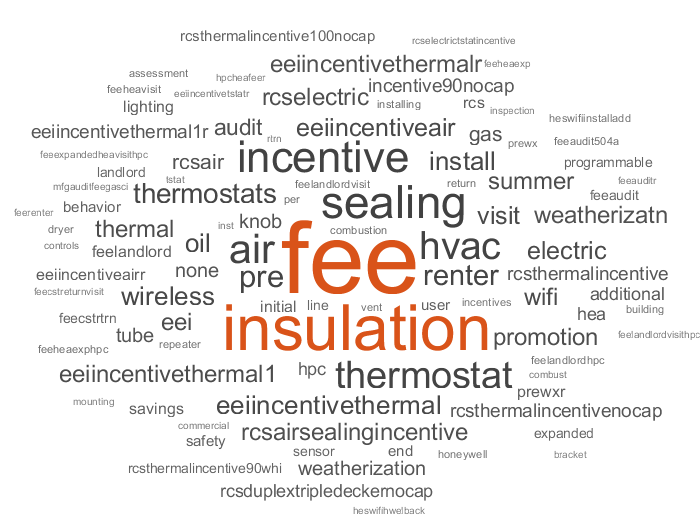

figure
NGram_CLoud1 = wordcloud(N_bag1);


N_bag2 = bagOfWords(Cluster_2_CL)

N_bag2 =   bagOfWords with properties:

          Counts: [136×204 double]
      Vocabulary: [1×204 string]
        NumWords: 204
    NumDocuments: 136


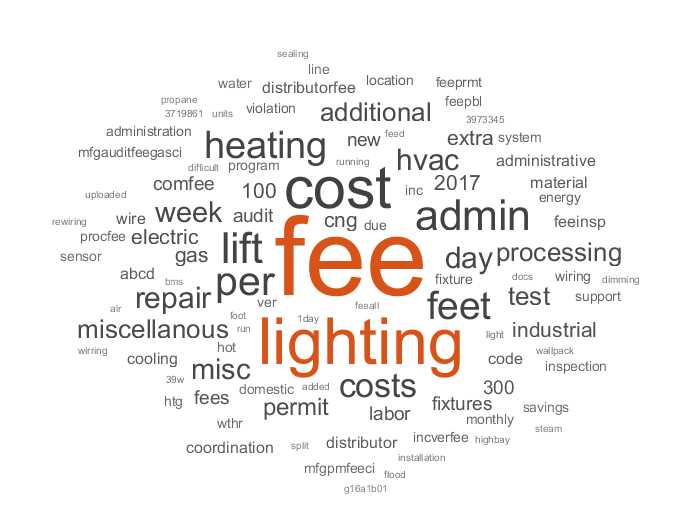

figure
NGram_CLoud2 = wordcloud(N_bag2);

function predata = preprocessText(textData)

predata=lower(textData);
predata=strtrim(predata);
predata=tokenizedDocument(predata);
predata=erasePunctuation(predata);
predata=removeStopWords(predata);
predata=removeShortWords(predata,2);

end